# **Discrete SEIR model for vector-borne diseases with a delay in Aquatic population with one pulse**

**Human population:**


$$H_s (t + 1) = H_s(t)\phi_m(t) (1  -  \mu_h) + N_H  \mu_h\\
H_i (t + 1) =H_s (t) (1 - \phi_m(t)) (1 - \mu_h) + H_i(t) (1 - \exp( - \gamma)) (1 - \mu_h)\\
H_r(t + 1) = H_r(t)  (1 - \mu_h)  + H_i(t)\exp(-\gamma) (1 - \mu_h) $$


**Mosquitoes population:**


$$M_s (t + 1) = M_s(t) \Psi_h(t)(1-exp(-\mu_m)) + A(t)\\
M_i (t + 1) =  M_s (1 - \Psi_h(t))  (1 - \exp( - \mu_m)) + M_i(t)(1 - \exp(- \mu_m ))$$


**With the following expressions:**

- **Mosquitoes interaction probability: **$\phi_m(t)=\left[ 1 - \frac{H_s(t) - 1}{H_s(t)} \right] ^{z_mM_i(t)\left[ \frac{H_s(t)}{N_H}\right] }$, with $N_H(t) = H_s(t) + H_i(t) + H_r(t) $

- **Human interaction probability: **$\Psi_h(t) = \left[ \frac{N_H + H_i(t)}{N_H(t)} \right]^{z_h}$, with $N_M(t) = M_s(t) + M_i(t)$

- **Recruitment expressions: ** 

- **Discrete Ricker:** $A(t) =   rN_M(t-2) \exp\left[ 1 -\frac{ N_M(t)}{C}\right]

$

**Parameters (unit time **$week^{-1}$** ):**

- $z$: number of interactions

- $\gamma$: recovery rate

- $\mu$: mortality rate

- $\alpha$: increase in mortality rate because of infection

- $r$: mosquitoes reproduction rate 

- $C$: Carrying capacity  

**Extra expressions**

- Muerte instantanea de mosquitos: $M_D(t) = (M_i(t) + M_e(t))\exp(-\alpha\mu) + M_s(t)\exp(-\mu)$ 

- Muerte instantanea de mosquitos: $H_{i_{ins}}(t) = H_e(t) \exp( - \delta_h)$

**Life-table papers**

[https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0229829#pone-0229829-t003](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0229829#pone-0229829-t003)

[https://www.researchgate.net/figure/Life-table-attributes-of-Aedes-aegypti-mosquito-from-the-western-region-of-Saudi-Arabia_tbl1_257985786](https://www.researchgate.net/figure/Life-table-attributes-of-Aedes-aegypti-mosquito-from-the-western-region-of-Saudi-Arabia_tbl1_257985786)

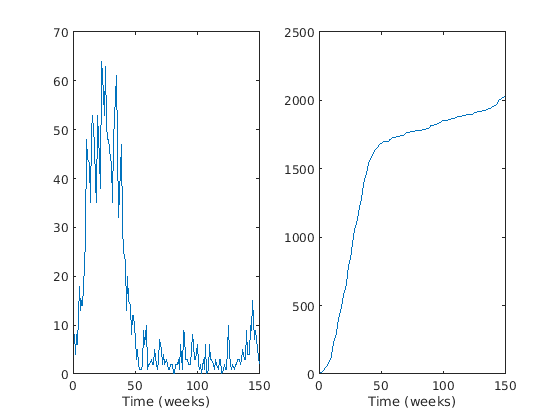

load('../Data/Data_Bello_2010_2014.mat')
m = 80;
ydata = yBello(1 : m)';
ydataCum = cumsum(yBello(1 : m))';

figure
subplot(1,2,1)
plot(ydata)
xlabel('Time (weeks)')

subplot(1,2,2)
plot(ydataCum)
xlabel('Time (weeks)')

VarNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D'};
% VarNames = {'H_S', 'H_I', 'H_R','M_I', 'M_D'};
OutNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D', 'H_{I_{ins}}','H_{I_{c}}', 'N_H'};
ParNames = {'\gamma', '\mu_m', '\mu_h', 'z', 'r', 'C', '\beta_m', '\beta_h', '\nu_m', '\nu_h'};
FullNames = [VarNames, ParNames];
ModelName = 'CHIMERA_Vector';

Range1 = [450000 450000;    %Hs
          1 20;       %Hi
          0 0;         %Hr
          10000 500000;    %Ms
          0 100;       %Mi
          0 0          %Md                     
    ];

Range2=[
       0.1 1;       %gamma 
       0 0.4;       %mu_m
       0 0;         %mu_h
       0 10;        %z
       0 60;       %r 
       1000 250000; %C
       0 1;         %beta_m
       0 1;         %beta_h  
       0 1000000;     %nu_m
       0 3000000      %nu_h
    ];

RangeT = [Range1; Range2];

D = 100;
Domain = [0 D-1];

[T,~] = gsua_dataprep(ModelName, RangeT, 'domain', Domain, 'names', FullNames, 'out_names', OutNames);

Setting environment to work with user-defined function


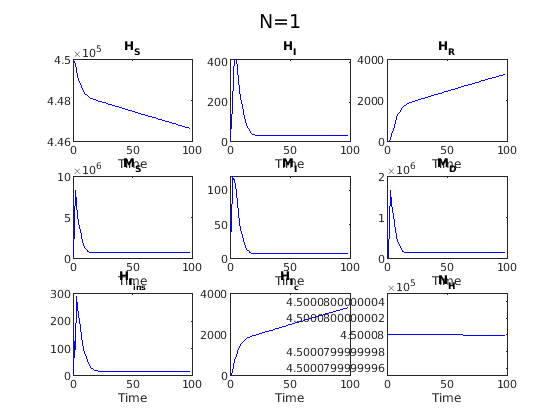

gsua_eval(T.Nominal, T);

D = length(ydata);
Domain = [0 D-1];
xdata = 0:D-1;

T = 12×3 table
                    Range           Nominal       Params  
               ________________    _________    __________

    H_I            1         20         10.5        7.9465
    M_S        10000      5e+05     2.55e+05    3.7737e+05
    M_I            0        100           50       0.42371
    \gamma       0.1          1         0.55       0.99996
    \mu_m          0        0.4          0.2      0.082064
    z              0         10            5        7.6155
    r              0         60           30    1.9423e-06
    C           1000    2.5e+05    1.255e+05         22513
    \beta_m        0          1          0.5       0.85297
    \beta_h        0          1          0.5      0.014562
    

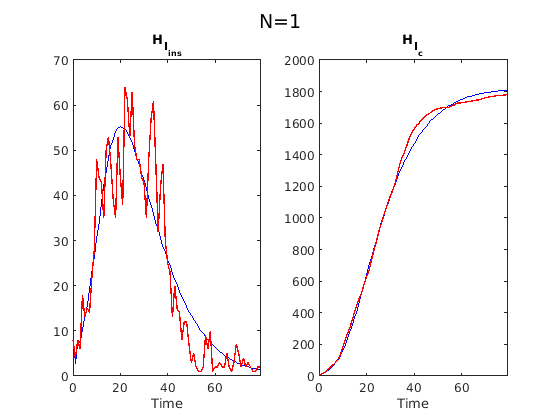

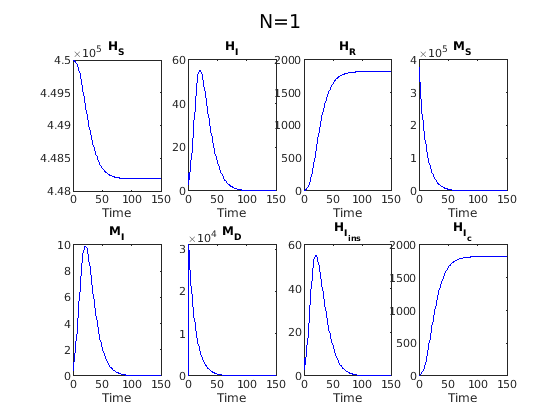

T.Properties.CustomProperties.Domain = Domain; 
T.Properties.CustomProperties.output = 7;

Solver = 'fmincon';

N = 1000;

    
Opt = optimoptions('fmincon','UseParallel', true, 'MaxFunctionEvaluations', 30000, ...
    'MaxIterations', 3000, 'Display','off');

parfor i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata,'solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estfmincon;
end

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

save("ResultsDengue/Estimations_Vector.mat", "EstimatedParams", "ResidualSorted")

T.Params = EstimatedParams(1,:)'
T.Properties.CustomProperties.output = [7 8];
gsua_eval(EstimatedParams(1,:)', T, xdata, [ydata; ydataCum]);
T.Properties.CustomProperties.Domain(2) = 150;

T.Properties.CustomProperties.output = 1:8;
gsua_eval(EstimatedParams(1,:)',T);
